Data

map =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     0     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     1     1     1     1     1     1     0     0     0     0     1     1     1     1     1     0     0     1
     1     0     1     1     1     1     1     1     0     0     0     0     1     1     1     1     1     0     0     1
     1     0     1     1     1     1     1     1     0     0     0     0     1     1     1     1     1     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     0     0     0  


ss = stateSpaceSE2

ss =   stateSpaceSE2 with properties:

                 Name: 'SE2'
          StateBounds: [3×2 double]
    NumStateVariables: 3
             WeightXY: 1
          WeightTheta: 0.1000


ss.StateBounds

ans =  -100.0000  100.0000
 -100.0000  100.0000
   -3.1416    3.1416


ss.StateBounds = [[0 50]; [0 50]; [-3.1416 3.1416]];
sv = validatorOccupancyMap(ss);



sv.Map = Map

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: Inf


sv.ValidationDistance = 0.01

sv =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: 0.0100


ss.StateBounds = [Map.XWorldLimits;Map.YWorldLimits;[-pi pi]];


planner = plannerRRT(ss,sv,MaxConnectionDistance=2);


rng(100, 'twister');
[pathObj, solvInf] = plan(planner, robot_pose, goal_pose)   

pathObj =   navPath with properties:

      StateSpace: [1×1 stateSpaceSE2]
          States: [13×3 double]
       NumStates: 13
    MaxNumStates: Inf


solvInf = struct with fields:
      IsPathFound: 1
         ExitFlag: 1
         NumNodes: 66
    NumIterations: 111
         TreeData: [200×3 double]


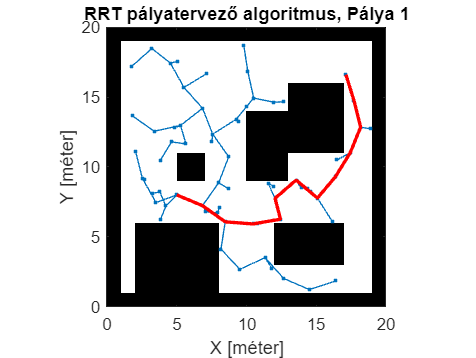



show(Map)
hold on
% Tree expansion
plot(solvInf.TreeData(:,1),solvInf.TreeData(:,2),'.-')
% Draw path
plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2)
title("RRT pályatervező algoritmus, Pálya 1")
xlabel("X [méter]")
ylabel("Y [méter]")

pathObj.States(:,1)

ans =     5.0000
    6.8470
    8.4747
   10.4690
   12.4368
   12.0459
   13.5559
   15.0849
   16.3720
   17.4254


pathObj.States(:,2)

ans =     8.0000
    7.2343
    6.0778
    5.9263
    6.2704
    7.7553
    9.0649
    7.7760
    9.3004
   10.9995
